# Solución Puntos

## P5: Iniciando

### P5.3 Modelo de robot IRB 2400 con RST

P5Considerando el robot asignado, construya el modelo del robot utilizando RST

!) asignación sistemas de coordenadas

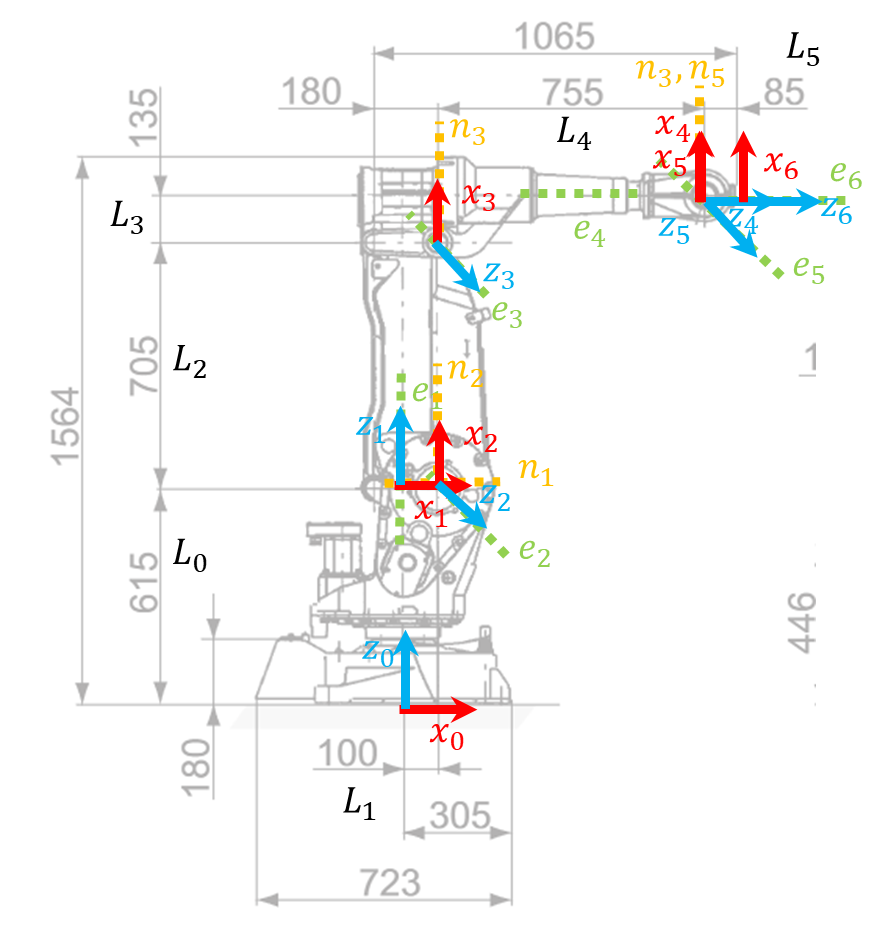

2) Parámetros DHmod

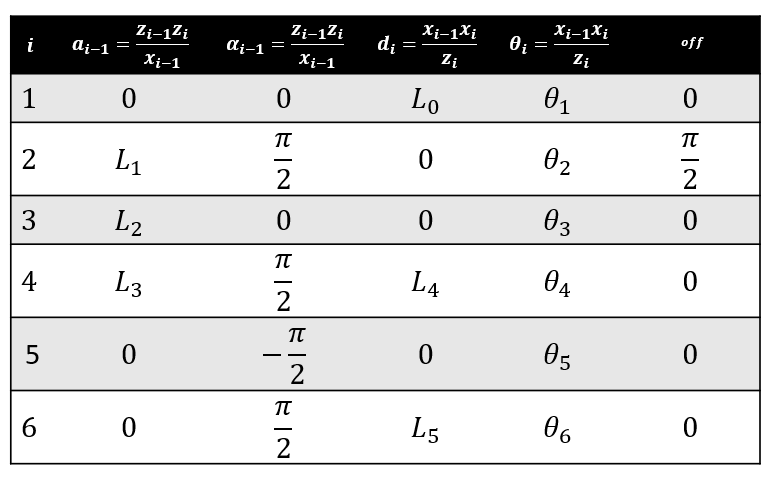

3) Usando Robotics System Toolbox, se obtiene el modelo de la siguiente manera

- Usando cuerpos rígidos

clear all;clf;clc;

robot = rigidBodyTree('DataFormat','column','MaxNumBodies',7);

L0 = 0.615;
L1 = 0.1;
L2 = 0.705;
L3 = 0.135;
L4 = 0.755;
L5 = 0.085;

% Se agrega Eslabón0 - Articulación0
body = rigidBody('link1');
joint = rigidBodyJoint('joint1', 'revolute');
setFixedTransform(joint,trvec2tform([0 0 0]));
joint.JointAxis = [0 0 1];
body.Joint = joint;
addBody(robot, body, 'base');

% Se agrega Eslabón1 - Articulación1
body = rigidBody('link2');
joint = rigidBodyJoint('joint2','revolute');
setFixedTransform(joint, trvec2tform([0,0,L0]));
joint.JointAxis = [0 0 1];
body.Joint = joint;
addBody(robot, body, 'link1');

% Se agrega Eslabón2 - Articulación2
body = rigidBody('link3');
joint = rigidBodyJoint('joint3','revolute');
setFixedTransform(joint, trvec2tform([L1,0,0])*eul2tform([pi/2 0 pi/2],'XYZ'));
joint.JointAxis = [0 0 1];
body.Joint = joint;
addBody(robot, body, 'link2');

% Se agrega Eslabón3 - Articulación3
body = rigidBody('link4');
joint = rigidBodyJoint('joint4','revolute');
setFixedTransform(joint, trvec2tform([L2,0,0]));
joint.JointAxis = [0 0 1];
body.Joint = joint;
addBody(robot, body, 'link3');

% Se agrega Eslabón4 - Articulación4
body = rigidBody('link5');
joint = rigidBodyJoint('joint5','revolute');
setFixedTransform(joint, trvec2tform([L3,-L4,0])*eul2tform([pi/2 0 0],'XYZ'));
joint.JointAxis = [0 0 1];
body.Joint = joint;
addBody(robot, body, 'link4');


% Se agrega Eslabón5 - Articulación5
body = rigidBody('link6');
joint = rigidBodyJoint('joint6','revolute');
setFixedTransform(joint, trvec2tform([0,0,0])*eul2tform([-pi/2 0 0],'XYZ'));
joint.JointAxis = [0 0 1];
body.Joint = joint;
addBody(robot, body, 'link5');

% Se agrega Eslabón efector final
body = rigidBody('link7');
joint = rigidBodyJoint('joint7','revolute');
setFixedTransform(joint, trvec2tform([0,-L5,0])*eul2tform([pi/2 0 0],'XYZ'));
joint.JointAxis = [0 0 1];
body.Joint = joint;
addBody(robot, body, 'link6');

show(robot)

ans =   Axes (Primary) with properties:

             XLim: [-2.5000 2.5000]
             YLim: [-2.5000 2.5000]
           XScale: 'linear'
           YScale: 'linear'
    GridLineStyle: '-'
         Position: [0.1300 0.1100 0.7750 0.8150]
            Units: 'normalized'

  Show all properties


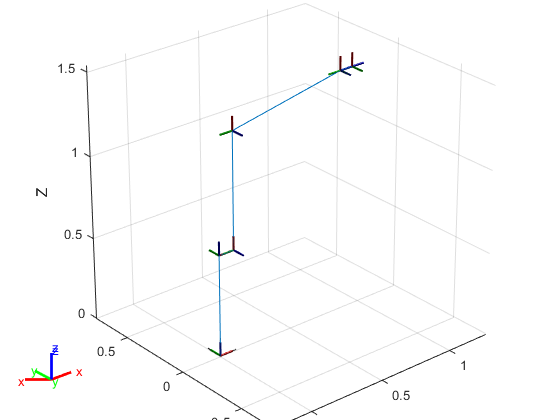

axis auto

view([-40.37 26.07])

- Usando matriz DHmod

dhparams = [0       0       L0      0;
            L1    pi/2       0   pi/2;
            L2      0        0      0;
            L3    pi/2      L4      0;
            0    -pi/2       0      0;
            0     pi/2      L5      0];    


robot2 = rigidBodyTree;
bodies = cell(6,1);
joints = cell(6,1);
%trotx(alpha)*transl(a,0,0)*trotz(theta_j)*transl(0,0,d_j)
for i = 1:6
    bodies{i} = rigidBody(['link' num2str(i)]);
    joints{i} = rigidBodyJoint(['joint' num2str(i)],"revolute");
    if dhparams(i,4)~= 0
        T1 = eul2tform([dhparams(i,2) 0 0],'XYZ')*trvec2tform([dhparams(i,1) 0 0]);
        T2 = eul2tform([0 0 dhparams(i,4)],'XYZ')*trvec2tform([0 0 dhparams(i,3)]);
        setFixedTransform(joints{i},T1*T2 );
    else
        setFixedTransform(joints{i},dhparams(i,:),"mdh");
    end
    bodies{i}.Joint = joints{i};
    if i == 1 % Add first body to base
        addBody(robot2,bodies{i},"base")
    else % Add current body to previous body by name
        addBody(robot2,bodies{i},bodies{i-1}.Name)
    end
end

showdetails(robot2)

--------------------
Robot: (6 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        link1        joint1      revolute             base(0)   link2(2)  
   2        link2        joint2      revolute            link1(1)   link3(3)  
   3        link3        joint3      revolute            link2(2)   link4(4)  
   4        link4        joint4      revolute            link3(3)   link5(5)  
   5        link5        joint5      revolute            link4(4)   link6(6)  
   6        link6        joint6      revolute            link5(5)   
--------------------


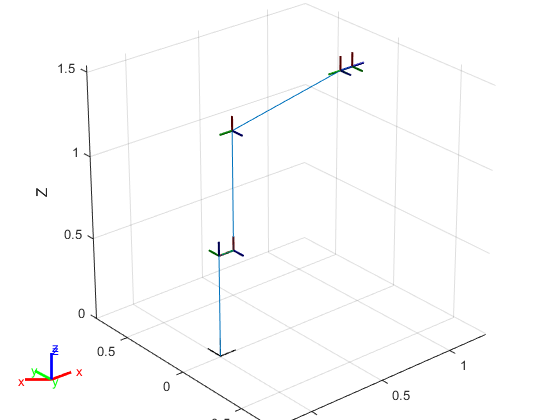

show(robot2);
axis auto
view([-40.37 26.07])

### **P6.3 Comparación de los métodos**

## P6:MODELO GEOMETRICO

### P6.1: Modelo geométrico RST

%RST no acepta valores simbólicos para los valores de las articulaciones
robot2

robot2 =   rigidBodyTree with properties:

     NumBodies: 6
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'link1'  'link2'  'link3'  'link4'  'link5'  'link6'}
      BaseName: 'base'
       Gravity: [0 0 0]
    DataFormat: 'struct'


%q = sym('q', [1 6])
articulaciones = zeros(1,6);
home_con = homeConfiguration(robot2);
% home_con(1).JointPosition = q(1)
% for i = 1:6
%     home_con(i).JointPosition = q(i)
% end
% home_con(1).JointPosition

CD = getTransform(robot2,home_con,'base','link6')

CD =     0.0000    0.0000    1.0000   -1.4550
   -0.0000   -1.0000    0.0000   -0.0000
    1.0000   -0.0000   -0.0000   -0.9400
         0         0         0    1.0000


### **P6.2: Representación Espacio alcanzable con RST**

Espacio  de trabajo alcanzable

Límites de acuerdo al manual de usuario

close all
q_lims = [-180 180; -110 110; -60 65; -200 220; -120 120; -400 400];
vpa(q_lims)

$$ans = \left(\begin{array}{cc} -180.0 & 180.0\\ -110.0 & 110.0\\ -60.0 & 65.0\\ -200.0 & 220.0\\ -120.0 & 120.0\\ -400.0 & 400.0 \end{array}\right)$$

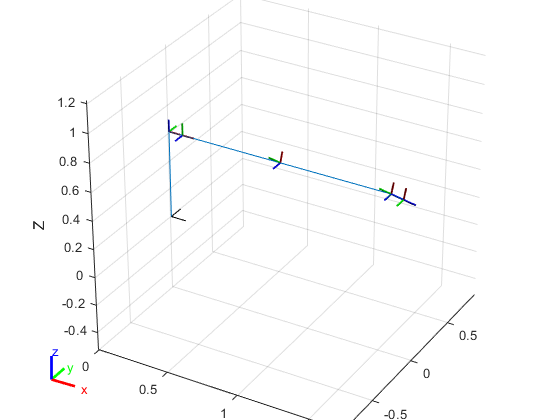

%q_lims = deg2rad(q_lims);
config = homeConfiguration(robot2);
config(2).JointPosition = deg2rad(-90);
off_q3 = atan2(L4,L3);
config(3).JointPosition = off_q3;
figure
show(robot2,config);
axis auto
view([30 30])
title('ubicación del brazo tal que forma que el brazo está totalmente extendido')

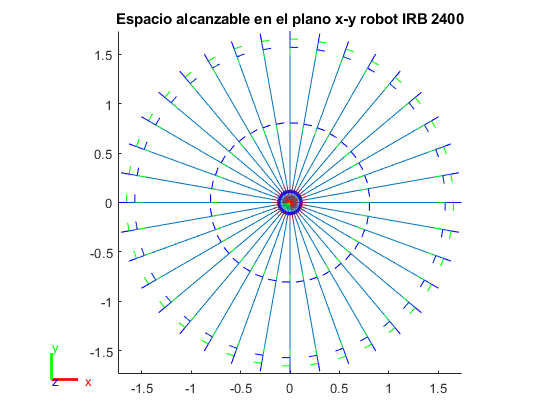


figure
%view([-40.37 26.07])
for i=q_lims(1,1):10:q_lims(1,2)
    config(1).JointPosition=deg2rad(i);
    hold on
    show(robot2,config);
end
axis equal
title('Espacio alcanzable en el plano x-y robot IRB 2400')
view([0 90])

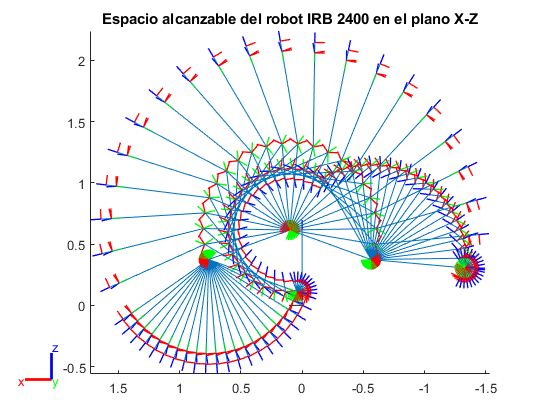

%2,3,4,5
close all

n = 22; %número de partes a dividir el intervalo
% Se dividen el intervalor entre los límites para las articulaciones
% 2,3,5
q2 = linspace(q_lims(2,1),q_lims(2,2),n);
q3 = linspace(q_lims(3,1),q_lims(3,2),n);
q5 = linspace(q_lims(5,1),q_lims(5,2),n);

figure
hold on
config = homeConfiguration(robot2);

%primer recorrido q2 variables q3,q5 constantes en máximo
config(3).JointPosition = deg2rad(q_lims(3,2));
config(5).JointPosition = pi/2-off_q3;%deg2rad(q_lims(5,2));
for i =1:n
    config(2).JointPosition = deg2rad(q2(i));    
    show(robot2, config);
end

%segundo recorrido q3 variable q2,q
config(2).JointPosition = deg2rad(q2(1));
%config(5).JointPosition = deg2rad(q_lims(5,2));
for i =1:n    
    config(3).JointPosition = deg2rad(q3(i));    
    show(robot2, config);
end

%tercer recorrido q5 variable q2,q3 contantes en el máximo
config(2).JointPosition = deg2rad(q2(1));
config(3).JointPosition = deg2rad(q3(1));
%config(5).JointPosition = deg2rad(q_lims(5,2));
for i =1:n
    if q5(i)<0
        config(5).JointPosition = deg2rad(q5(i));
        show(robot2, config);
    end
end

% cuarto recorrido vuelta al inicio
config(3).JointPosition = deg2rad(q_lims(3,1));
config(5).JointPosition = deg2rad(q_lims(5,1));
for i =1:n
    config(2).JointPosition = deg2rad(q2(i));
    show(robot2, config);
end

% quinto recorrido vuelta al inicio q3 variable q2,q5 constantes
config(2).JointPosition = deg2rad(q_lims(2,2));
config(5).JointPosition = deg2rad(q_lims(5,1));
for i =1:n
    config(3).JointPosition = deg2rad(q3(i));
    show(robot2, config);
end

% sexto recorrido vuelta al inicio q5 variable q2,q3 constantes
config(2).JointPosition = deg2rad(q_lims(2,2));
config(3).JointPosition = deg2rad(q_lims(3,2));
for i =1:n
    config(5).JointPosition = deg2rad(q5(i));
    show(robot2, config);
end
axis equal
view([0 2 0])
title('Espacio alcanzable del robot IRB 2400 en el plano X-Z')

### P6.3: Puntos de calibración RST

De acuerdo con la hoja de datos, se tienen los siguientes puntos de calibración:

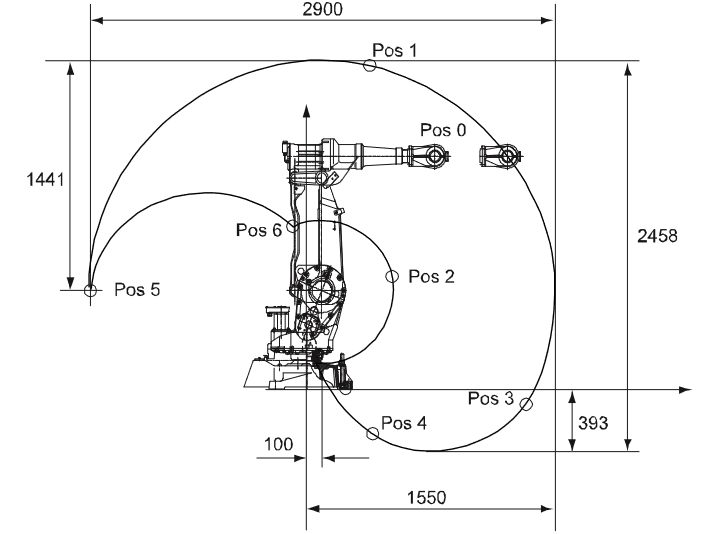

Con la siguiente información:

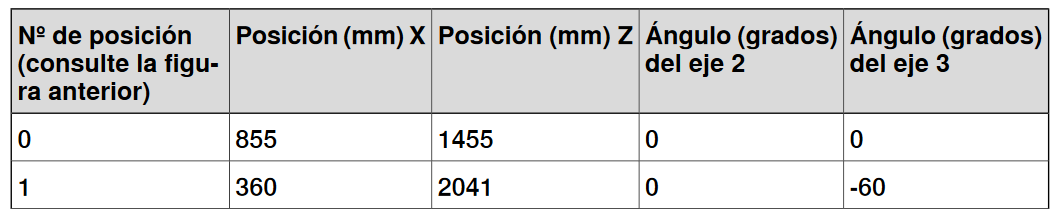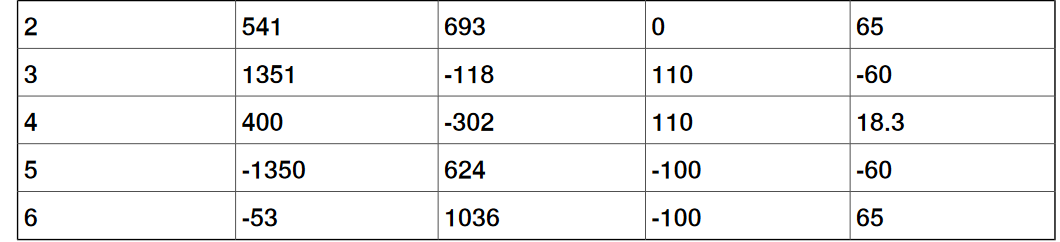

**Nota**: De acuerdo con la asignación de sistemas de referencia en el punto 4, los ángulos para el eje 3 son negativos con respecto a los de la tabla.

robot2

robot2 =   rigidBodyTree with properties:

     NumBodies: 6
        Bodies: {[1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]  [1×1 rigidBody]}
          Base: [1×1 rigidBody]
     BodyNames: {'link1'  'link2'  'link3'  'link4'  'link5'  'link6'}
      BaseName: 'base'
       Gravity: [0 0 0]
    DataFormat: 'struct'


showdetails(robot2)

--------------------
Robot: (6 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        link1        joint1      revolute             base(0)   link2(2)  
   2        link2        joint2      revolute            link1(1)   link3(3)  
   3        link3        joint3      revolute            link2(2)   link4(4)  
   4        link4        joint4      revolute            link3(3)   link5(5)  
   5        link5        joint5      revolute            link4(4)   link6(6)  
   6        link6        joint6      revolute            link5(5)   
--------------------


pos_cal = [   0    0; 
              0  -60; 
              0   65;
            110  -60;
            110 18.3;
           -100  -60;
           -100   65;];
vpa(pos_cal)

$$ans = \left(\begin{array}{cc} 0 & 0\\ 0 & -60.0\\ 0 & 65.0\\ 110.0 & -60.0\\ 110.0 & 18.3\\ -100.0 & -60.0\\ -100.0 & 65.0 \end{array}\right)$$



config2 = homeConfiguration(robot2);
figure
hold on
grid on
for i=1:size(pos_cal)
    config2(2).JointPosition = -deg2rad(pos_cal(i,1));
    config2(3).JointPosition = -deg2rad(pos_cal(i,2));
    T05 = getTransform(robot2,config2,'link5','base');
    pos = round(T05(1:3,4),3);
    vpa(pos')
    show(robot2,config2);
    text(pos(1),pos(2),pos(3),['pos' num2str(i-1)])
end

$$ans = \left(\begin{array}{ccc} 0.855 & 0 & 1.455 \end{array}\right)$$

$$ans = \left(\begin{array}{ccc} 0.361 & 0 & 2.041 \end{array}\right)$$

$$ans = \left(\begin{array}{ccc} 0.541 & 0 & 0.693 \end{array}\right)$$

$$ans = \left(\begin{array}{ccc} 1.351 & 0 & -0.118 \end{array}\right)$$

$$ans = \left(\begin{array}{ccc} 0.4 & 0 & -0.302 \end{array}\right)$$

$$ans = \left(\begin{array}{ccc} -1.35 & 0 & 0.624 \end{array}\right)$$

$$ans = \left(\begin{array}{ccc} -0.053 & 0 & 1.036 \end{array}\right)$$

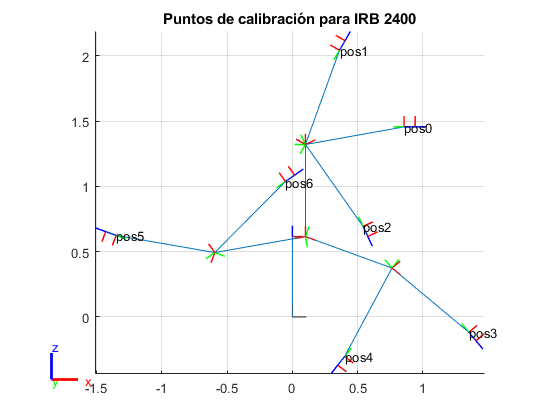

beta = 0.1769

ans = 10.1378

x = 0.2606

y = 0.7213

xf = 0.3606

yf = 2.0413

axis equal
view([0 -2 0])
title('Puntos de calibración para IRB 2400')